# Oxygen Cylinder

## INITIALIZE UQLAB

clc; clear all; close all;
uqlab;

Copyright 2013-2024, Stefano Marelli and Bruno Sudret.
This is UQLab, version 2.1
UQLab is distributed under the BSD 3-clause open source license available at: 
<a href="https://uqlab.com/license">https://uqlab.com/license</a>.

To request special permissions, please contact:
  - Stefano Marelli (<a href="mailto:marelli@ibk.baug.ethz.ch">marelli@ibk.baug.ethz.ch</a>).

Useful commands to get started with UQLab:
uqlab -doc           - Access the available documentation
uqlab -help          - Additional help on how to get started with UQLab
uq_citation help   - Information on how to cite UQLab in publications
uqlab -license       - Display UQLab license information



## COMPUTATIONAL MODEL

The **P** function is defined as:


$$g(\mathbf{P}) = 5P-155$$


Create a limit state function model using a string, written below in a vectorized operation:

ModelOpts.mString = 'X(:,1) -155'; 
ModelOpts.isVectorized = true;

myModel = uq_createModel(ModelOpts);

## PROBABILISTIC INPUT MODEL

The probabilistic input model consists of two independent Gaussian random variables:


$$p \sim \mathcal{N}(30, 2)$$


Specify the probabilistic input model for the p:

InputOpts.Marginals(1).Name = 'P';  % resistance variable
InputOpts.Marginals(1).Type = 'Gaussian';
InputOpts.Marginals(1).Moments = [30 2]; % mean and std dev

Create an INPUT object based on the specified marginals:

myInput = uq_createInput(InputOpts);

## FORM

Select FORM as the reliability analysis method:

FORMOpts.Type = 'Reliability';
FORMOpts.Method = 'FORM';

Run the FORM analysis:

FORMAnalysis = uq_createAnalysis(FORMOpts);


Starting FORM Analysis...

FORM: Finished.


Print out a report of the results:

uq_print(FORMAnalysis)

---------------------------------------------------
FORM
---------------------------------------------------
Pf               0001             
BetaHL           -62.5000         
ModelEvaluations 6                
---------------------------------------------------
Variables        P           
  Ustar          62.500000   
  Xstar          155         
  Importance     1.000000    
---------------------------------------------------



Create a graphical representation of the results:

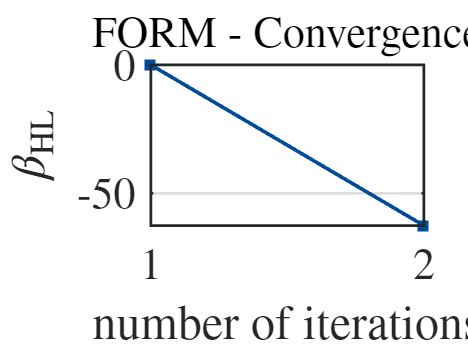


Starting FORM Analysis...

FORM: Finished.


---------------------------------------------------
FORM
---------------------------------------------------
Pf               0001             
BetaHL           -62.5000         
ModelEvaluations 6                
---------------------------------------------------
Variables        P           
  Ustar          62.500000   
  Xstar          155         
  Importance     1.000000    
---------------------------------------------------




Starting FORM/SORM Analysis...

SORM: FORM Results not found
SORM: Starting FORM to search for the design point...
FORM: Finished.

SORM: Finished.
 

---------------------------------------------------
FORM/SORM
---------------------------------------------------
Pf               0001             
BetaHL           -62.5000         
PfFORM           0001             
PfSORM           0001             
PfSORMBreitung   0001             
ModelEvaluations 15               
---------------------------------------------------
Variables        P           
  Ustar          62.500000   
  Xstar          155         
  Importance     1.000000    
---------------------------------------------------



uq_display(FORMAnalysis)

## Monte Carlo simulation (MCS)

Select the Reliability module and the Monte Carlo simulation (MCS) method:

MCSOpts.Type = 'Reliability';
MCSOpts.Method = 'MCS';

Specify the maximum sample size: 

MCSOpts.Simulation.MaxSampleSize = 1e6;

Run reliability analysis with MCS:

MCSAnalysis = uq_createAnalysis(MCSOpts);


Starting Crude Monte Carlo Analysis...

MC: Finished.
 

Print out a report of the results:

uq_print(MCSAnalysis)

---------------------------------------------------
Monte Carlo simulation
---------------------------------------------------
Pf               0001             
Beta             -Inf             
CoV              0                
ModelEvaluations 1000000          
PfCI             [1.0000e+00 1.0000e+00]
BetaCI           [-Inf       -Inf      ]
---------------------------------------------------



Create a graphical representation of the results:

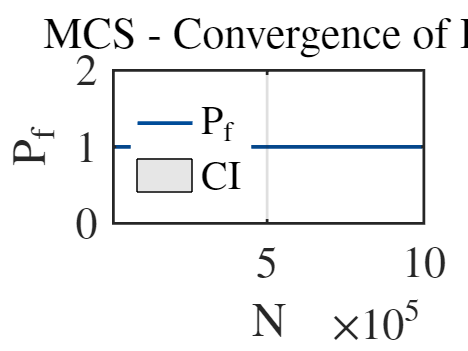

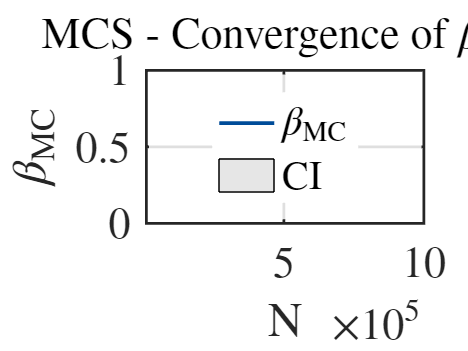

uq_display(MCSAnalysis)